## Classification of the Antarctic sea ice cover

% Setup
clear all
clc
close all
addpath functions
addpath /Users/noahday/GitHub/CICE-analyser/processing

historydir = '/Users/noahday/Maths1/access-forcing-2010-fixed-ic/history/';

a = dir([historydir '/*.nc']);
n_files = numel(a);

for i = 1:n_files
   filenames(i,:) = strcat(historydir,a(i).name);
   dirdates(i,:) = a(i).name(6:end-3);
end


%% PCA for CICE data
% Columns are data
sector = "SH";
close all
i = 7;
var_list = {'aice','hi','iage','fsdrad','pancake','large','wave_sig_ht','daidtd','daidtt','sice','frzmlt','congel','frazil','meltb','ice_present','peak_period','strint','strocn','strair','strcor','vel','atmspd','Tair'};
[X_total]= read_data_vec(filenames(i,:),sector,var_list);
label_vec = variable_dict(var_list);
%% Clean the data
clc
clear X_new
% Step 0: removing NaNs
idx1 = isnan(X_total);
idx = logical(idx1);
[len, wid] = size(X_total);
wid = wid - 2;
count = 1;
for j = 1:len
    if sum(idx(j,:)) == 0
        X_new(count,:) = X_total(j,:);
    count  = count + 1;
    end
end
X_new_unstandard = X_new;

% Step 1: Standardization

for j = 1:wid
    % Calculate mean
    mean_X(j) = mean(X_new(:,j));
    % Calculate standard deviation
    std_X(j) = std(X_new(:,j));
    % Standardise the data
    X_new(:,j) = (X_new(:,j) - mean_X(j))/std_X(j);
end

disp('X_new done')

X_new done


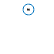



% Step 2: Covariance analysis  
X_cov = X_new(:,1:wid);
% C = cov(X_cov);
% close all
% figure;
% R = corrplot(double(X_cov),'varNames',label_vec);

% conFigure(11,1)
% [~, h_corrmat, h_colorbar] = plot_corrmat([],... % leave timeSeries input empty, since already calculated corrmat
%    'corrmat', R,... % the correlation matrix
%    'title', 'Ice conditions',... % plot title
%    'labels', {'aice','pan prev.','thickness','iage','fsdrad'},... % correlation matrix cell labels
%    'label_FontSize', 11,... % long labels get cutoff with larger fonts
%    'outline', 1); % outline the cells (appearance improvement)

%% plotting cluster analysis

f = figure;
[coeff,score,latent,tsquared,explained] = pca(X_cov);
% The rows of coeff contain the coefficients for the five ice variables, and its columns correspond to five principal components.
% Each column of score corresponds to one principal component. 
% The vector, latent, stores the variances of the five principal components.

% Reconstruct the centered ingredients data.
Xcentered = score*coeff';

scatter(score(:,1),score(:,2),'o')
axis equal
xlabel('1st Principal Component')
ylabel('2nd Principal Component')

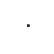



f = figure;
bar(1:numel(explained),explained)
ylabel('$\%$ of variance explained','Interpreter','latex')
xlabel("Principal components",'Interpreter','latex')

%exportgraphics(f,'percentageofvariance.pdf','ContentType','vector')
fprintf('%g percent of the variance is explained by the first two principal components', sum(explained(1:2)))

60.0809 percent of the variance is explained by the first two principal components

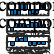

% 
% figure
% for i = 1:numel(explained)
%    subplot(3,1,i)
%    hist(score(:,i))%,'varlabels',{'aice','pancake prev.','thickness','age','fsdrad','SWH'});
% end

%close all
f = figure;
for i = 1:3
 subplot(3,1,i)
 temp = coeff(:,i);
 idx = abs(temp) > 1/sqrt(length(temp));
 loadings = temp(idx);
 loadings_label = label_vec(idx);
 bar(loadings)
 xticks(1:length(loadings))
 set(gca, 'XTickLabel',loadings_label)
 title(sprintf('PCA component %g',i))
 ylabel('Loadings')
end

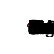

% legend(label_vec)
%x = X
%plot3(score(:,1),score(:,2),score(:,3),'bo')

%label_vec = var_list;
f = figure;
biplot(coeff(:,1:2),'scores',score(:,1:2),'varlabels',label_vec(1:length(coeff))); 

%exportgraphics(f,'PCAbiplot.pdf','ContentType','vector')

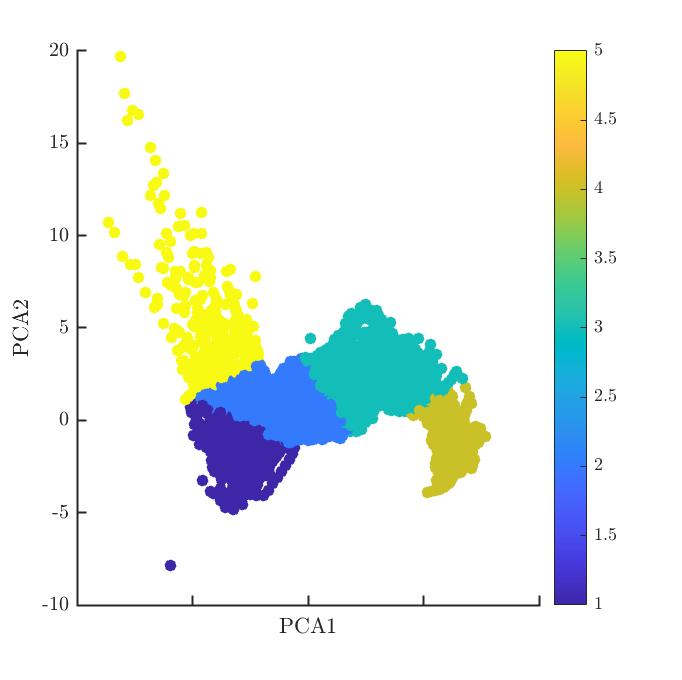


%% Clustering
X = score(:,1:2);
close all
%rng(1); % For reproducibility
num_clusters = 5;
[idx,C] = kmeans(X,num_clusters);

x1 = linspace(min(X(:,1)),max(X(:,1)),1000);%min(X(:,1)):0.5:max(X(:,1));
x2 = linspace(min(X(:,2)),max(X(:,2)),1000);%min(X(:,2)):0.5:max(X(:,2));
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot

idx2Region = kmeans(XGrid,num_clusters,'MaxIter',100,'Start',C);

conFigure(12,1)
figure;
subplot(1,1,1);
gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
    [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
hold on;
plot(X(:,1),X(:,2),'k*','MarkerSize',5);
hold off
%plotv(coeff(:,1:2))
%xlabel 'Pancake prevalance [$\%$]'; 
set(gca,'xticklabel',{[]})
ylabel 'PCA2';
xlabel 'PCA1';
legend off
%legend('Region 1','Region 2','Region 3','Data','Location','NorthEast');

hold off;
% New clustering model?

% Plot scatter with dots matching the colour of each region!
f = figure;
scatter(X(:,1),X(:,2),[],idx,'filled');
set(gca,'xticklabel',{[]})
ylabel 'PCA2';
xlabel 'PCA1';
colorbar
legend off
exportgraphics(f,'cluster.pdf','ContentType','vector')

## Plot worldmap

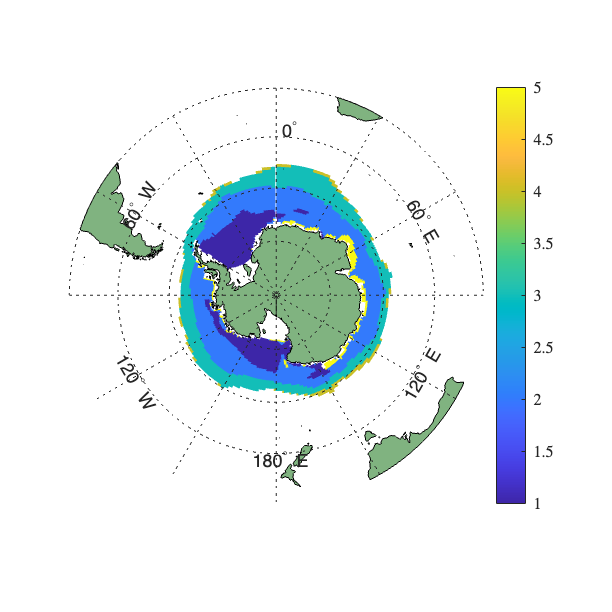

[lat,lon,~,ulat,ulon] = grid_read('om2');
clear X_map
% Make worldmap with colour matching
[len,wid] = size(lat);
X_map = [idx, X_new(:,end-1:end)];
k_means = NaN.*ones(len,wid);
for i = 1:length(idx)
    lat_pos = near1(lat(180,:),X_map(i,2));
    lon_pos = near1(lon(:,180),X_map(i,3));

    %lat_pos = 
    %lon_pos
    k_means(lon_pos,lat_pos) = idx(i); 
end
%map_data = [X_new(:,end-1:end);
    aice = data_format_sector(filenames(7,:),'aice',sector);
    ice_mask =  aice > 0.15;
    k_means(~ice_mask) = NaN;

f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-30]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off') 
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'grid', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,k_means)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    %cmocean('balance',31)
    %caxis([0,1])
exportgraphics(f,'map.pdf','ContentType','vector')

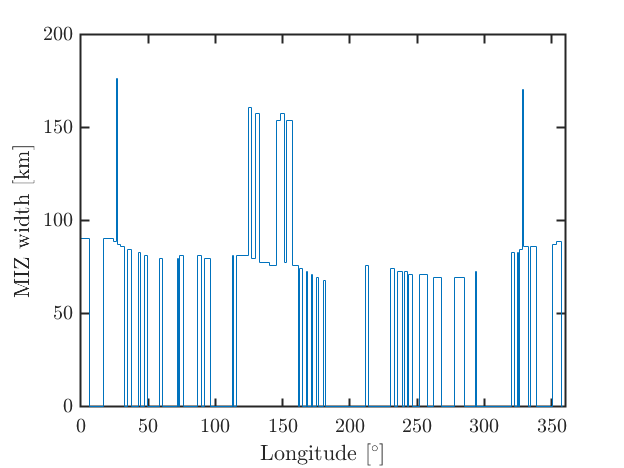


    % Calculate the width of the MIZ

    % CHECK WHAT number MIZ is !!!!!!!!
    MIZ_width = calculate_miz_width(filenames(7,:),sector,k_means);

    conFigure(11,3)
    f = figure;
    stairs(lon(1:end-1,1),MIZ_width(1:end-1))
    ylabel('MIZ width [km]')
    xlabel('Longitude [$^\circ$]')
    xlim([0,360])


    %exportgraphics(f,'mizwidth.pdf','ContentType','vector')

sprintf('The mean MIZ width is: %g [km]',mean(MIZ_width(1:end-1)))

ans = 'The mean MIZ width is: 37.594 [km]'

## Gif of MIZ

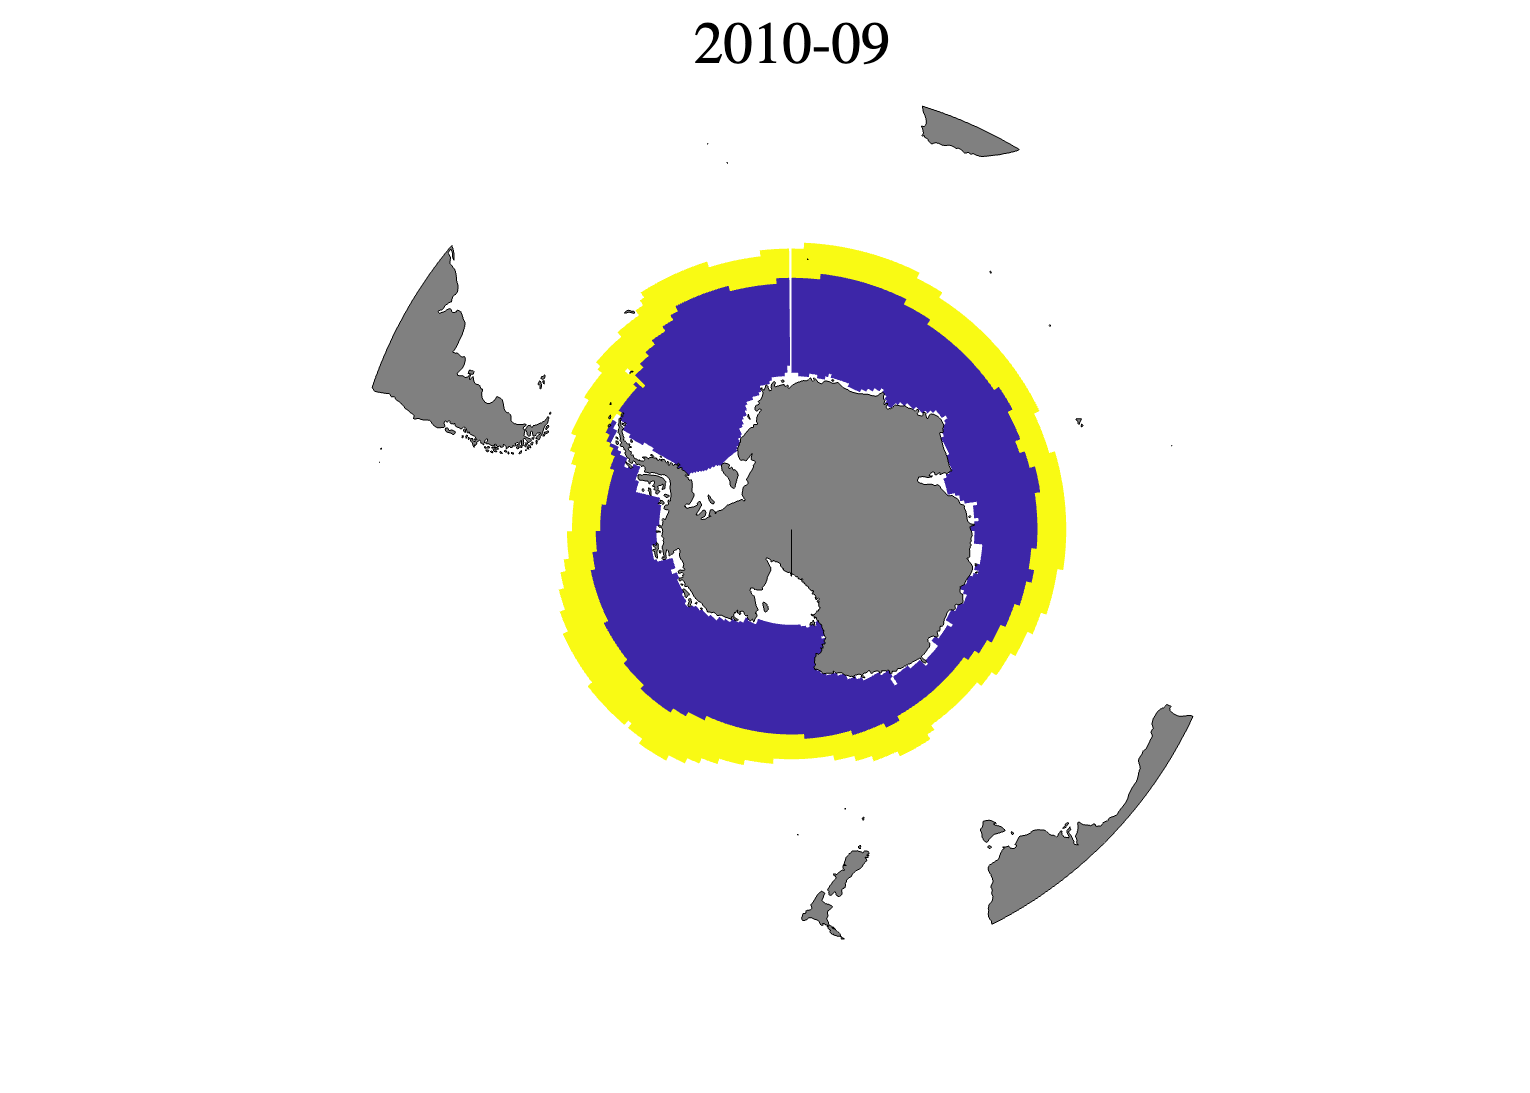

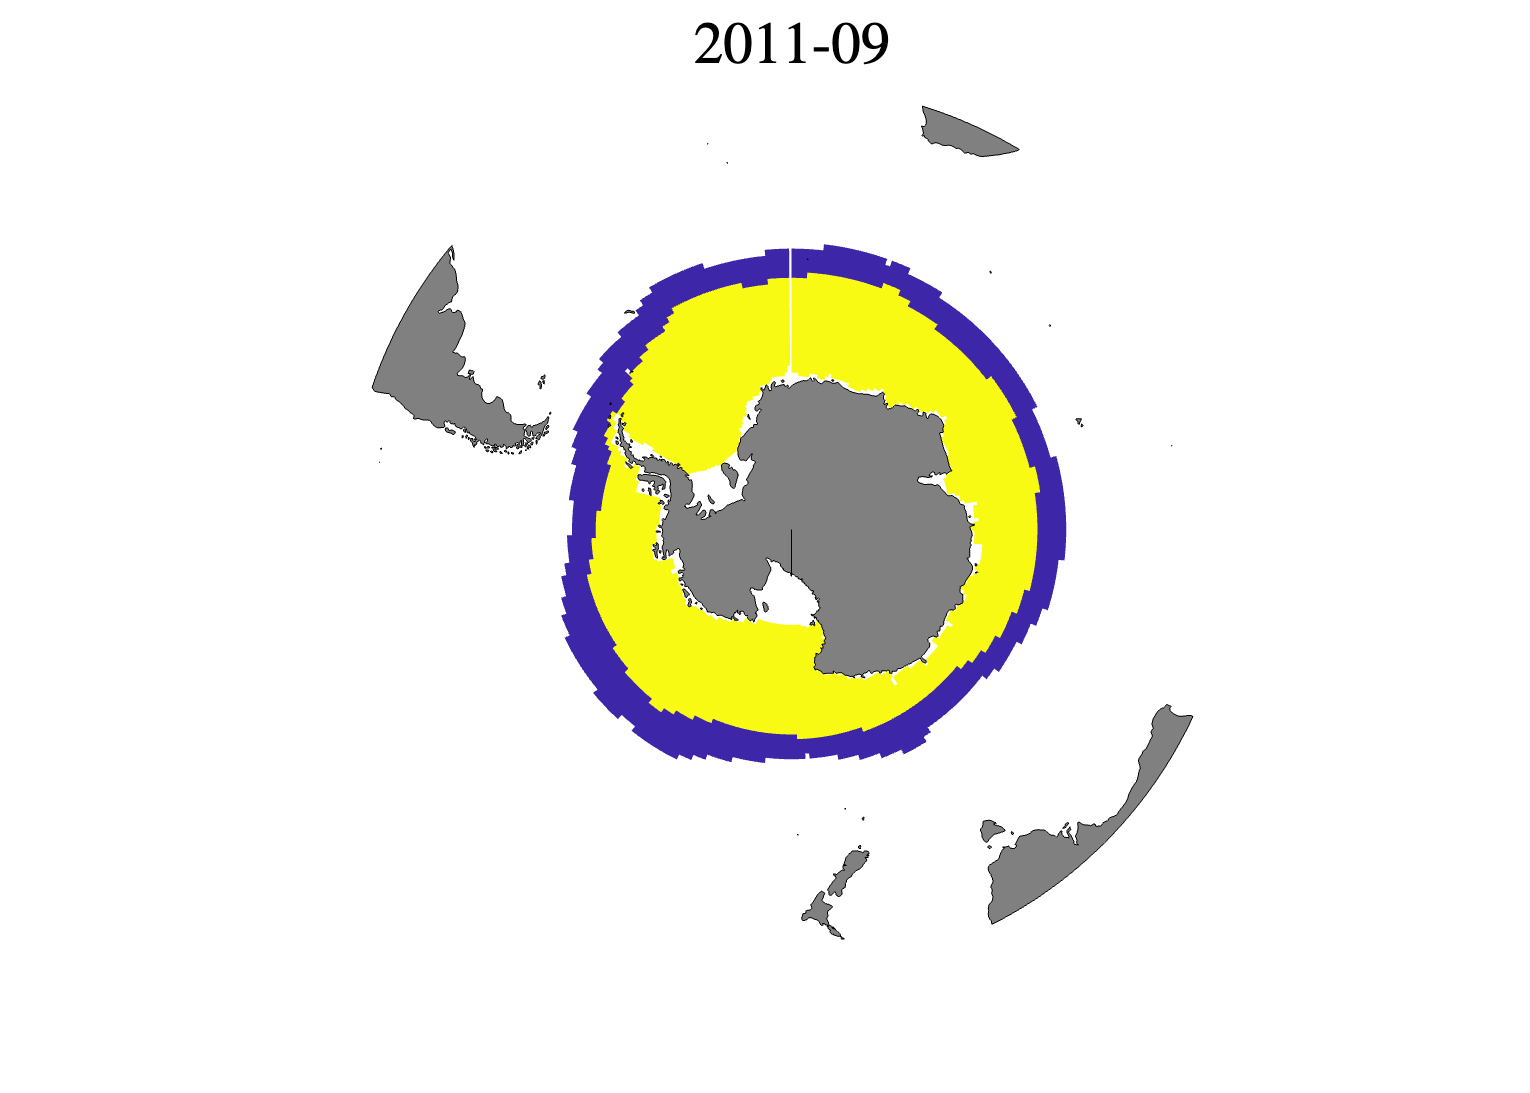

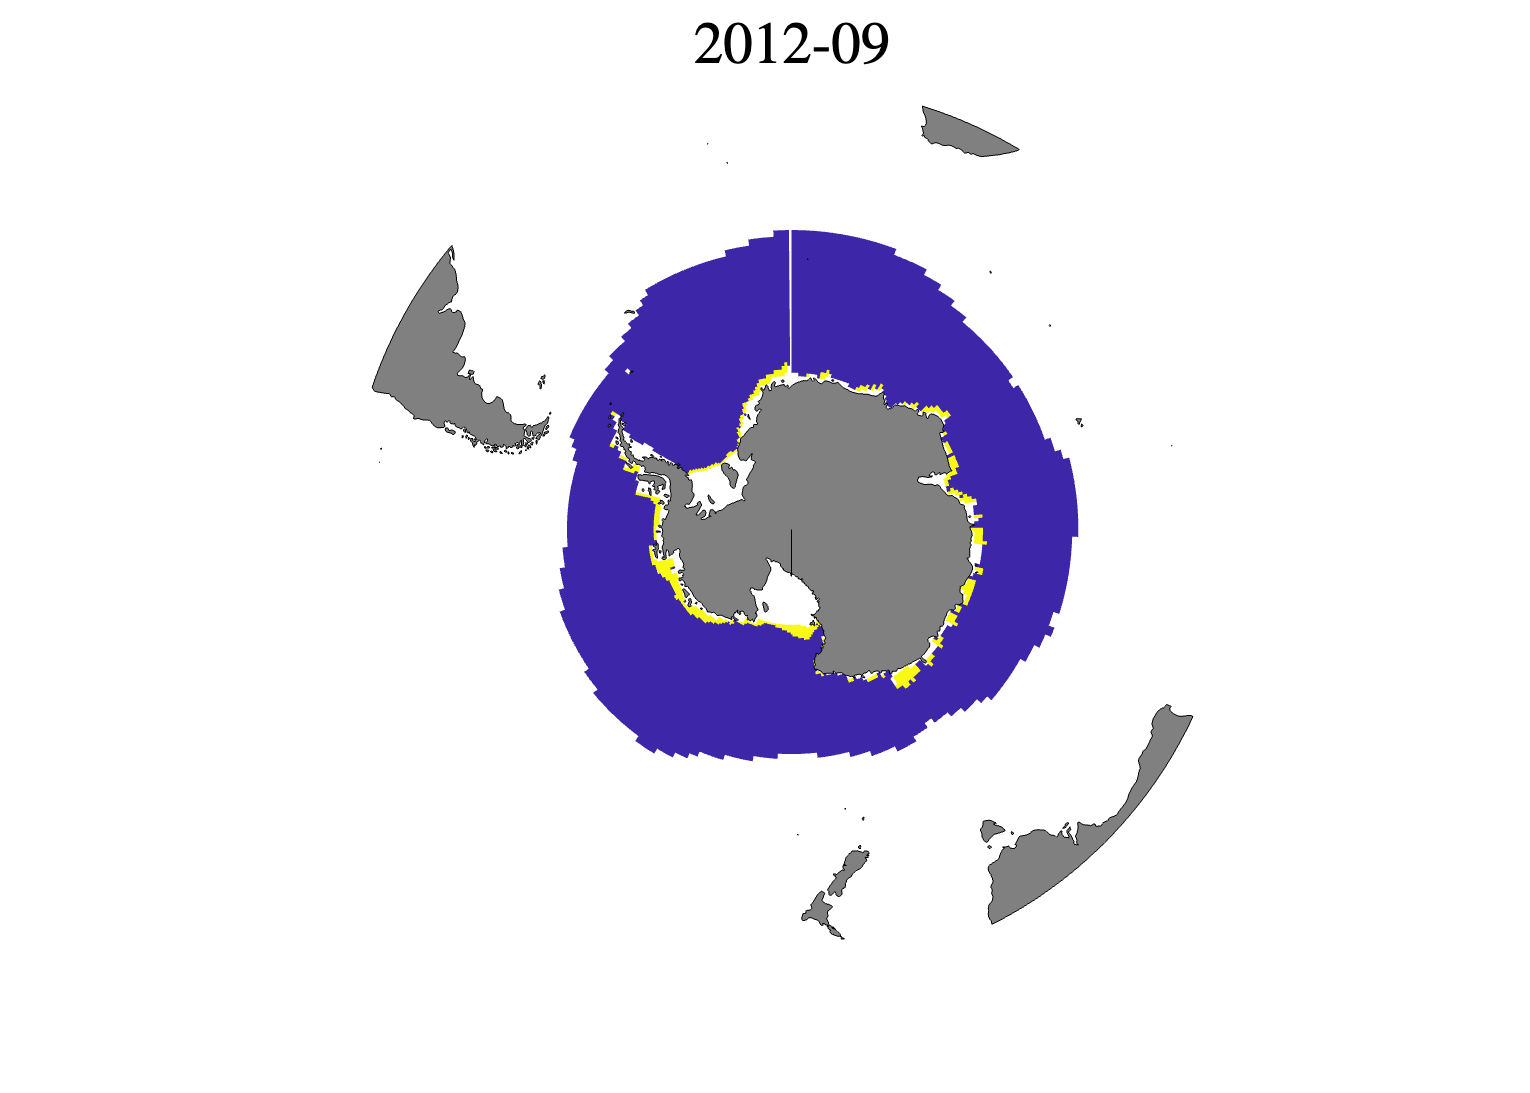

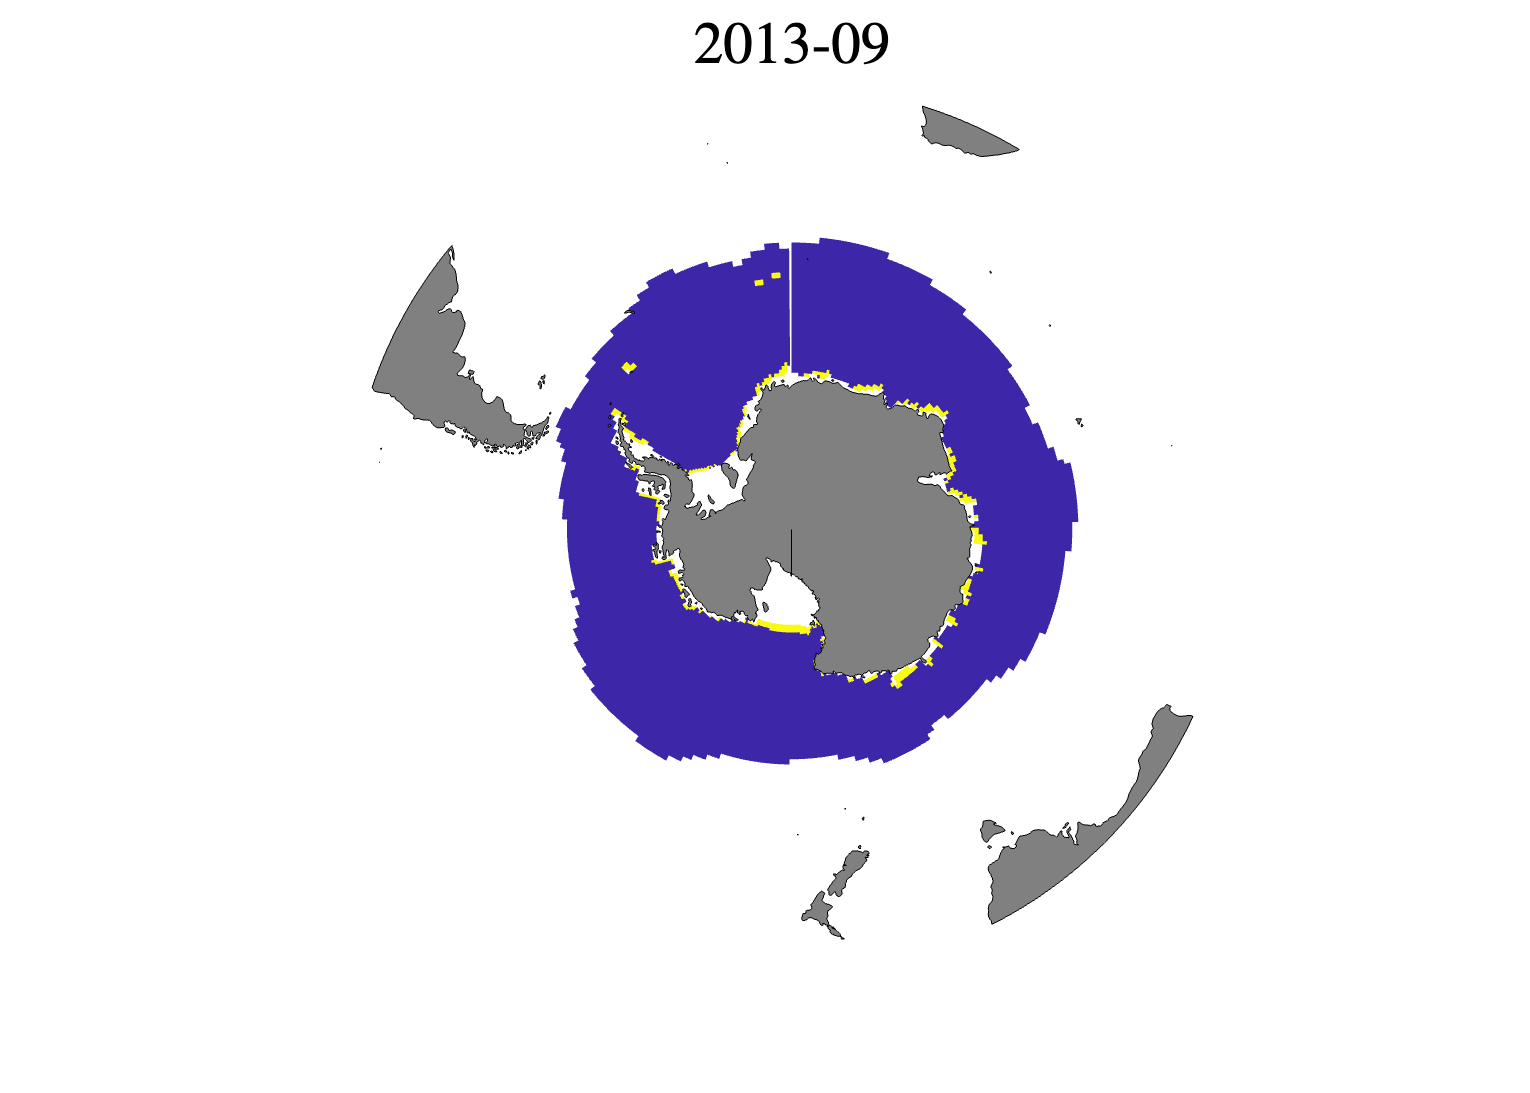

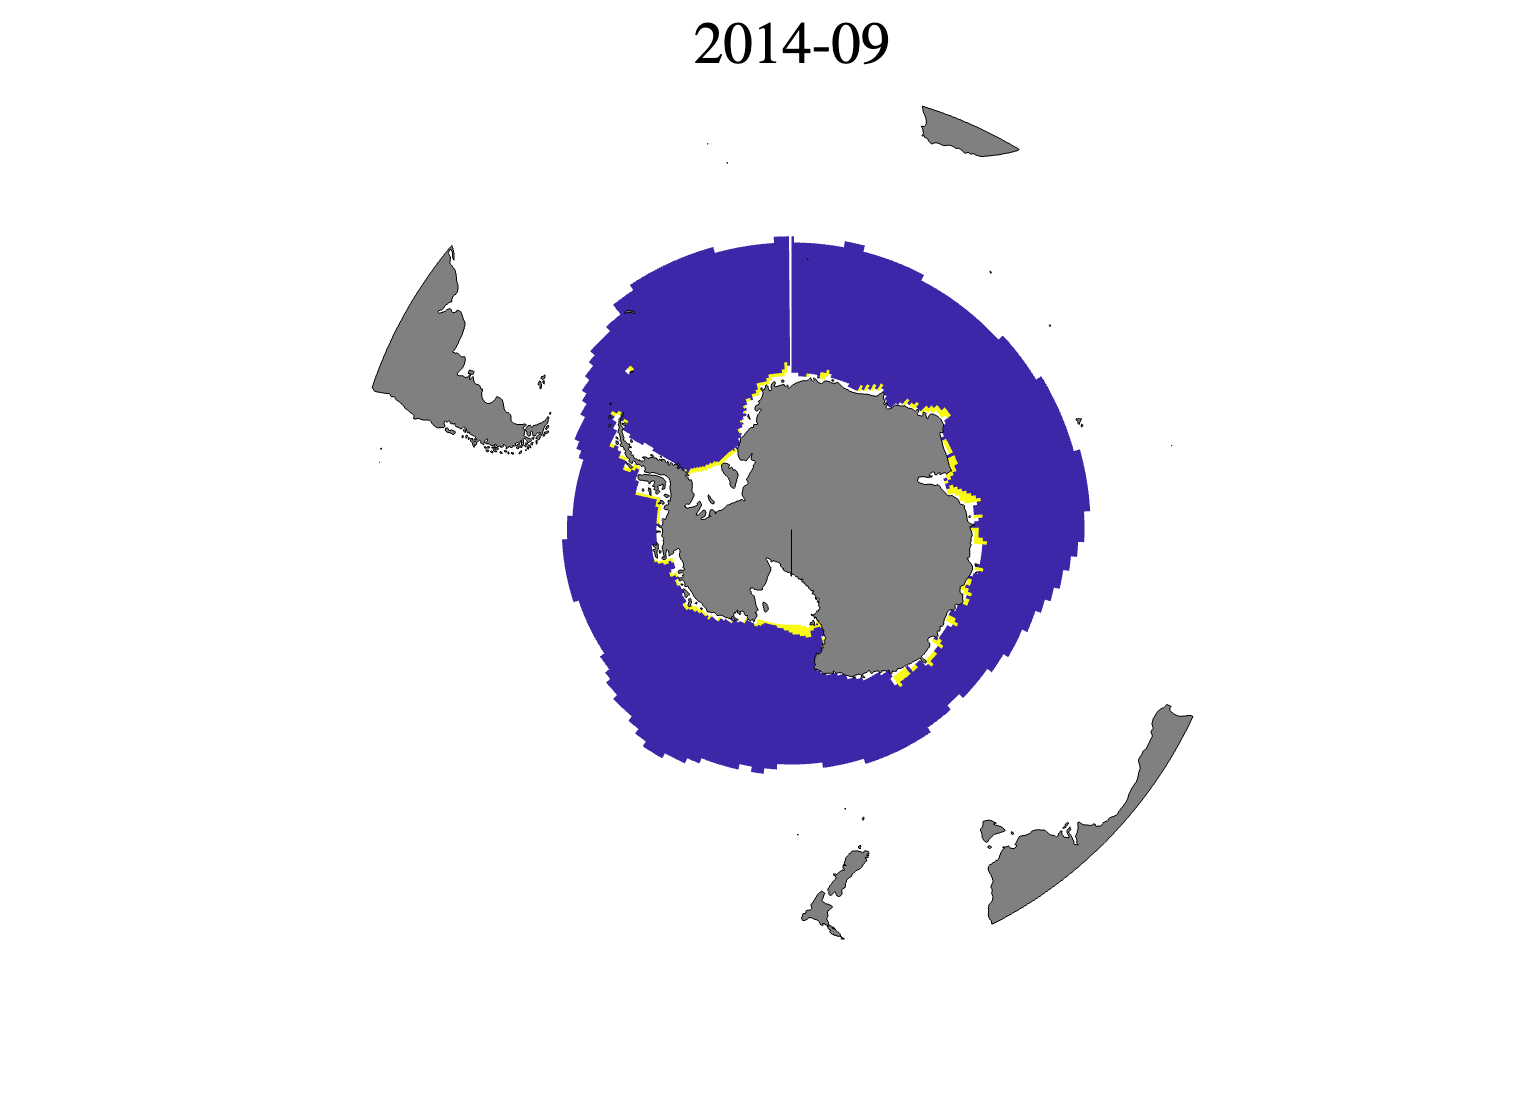

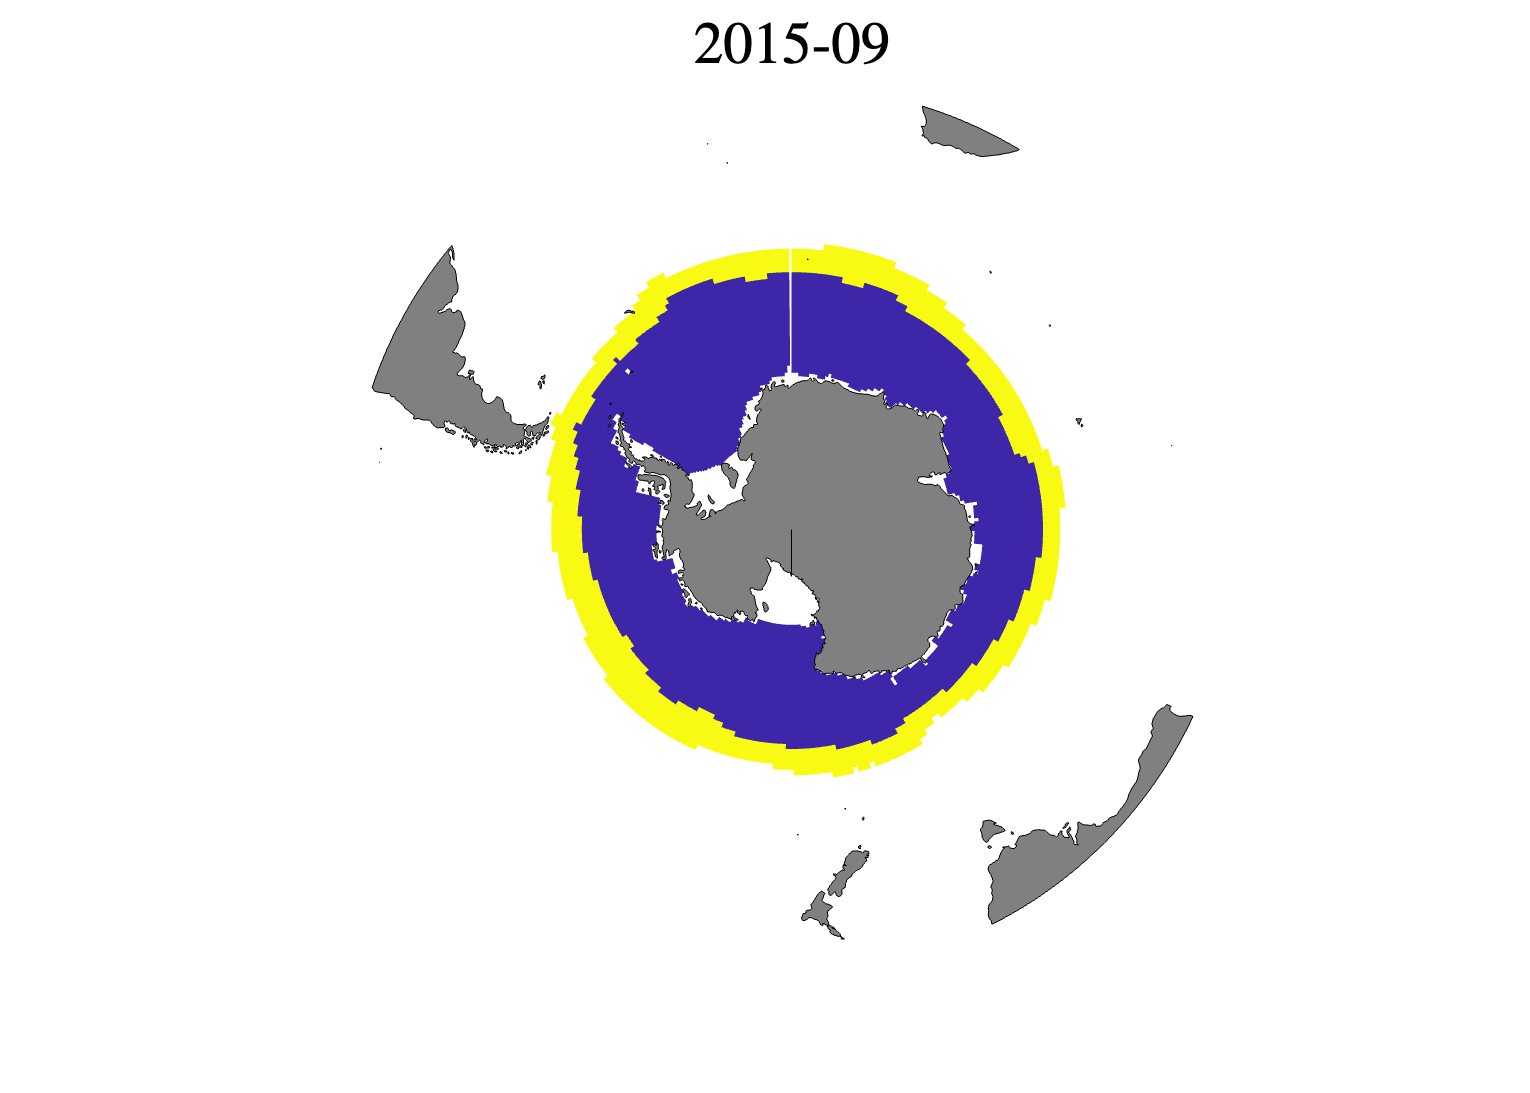

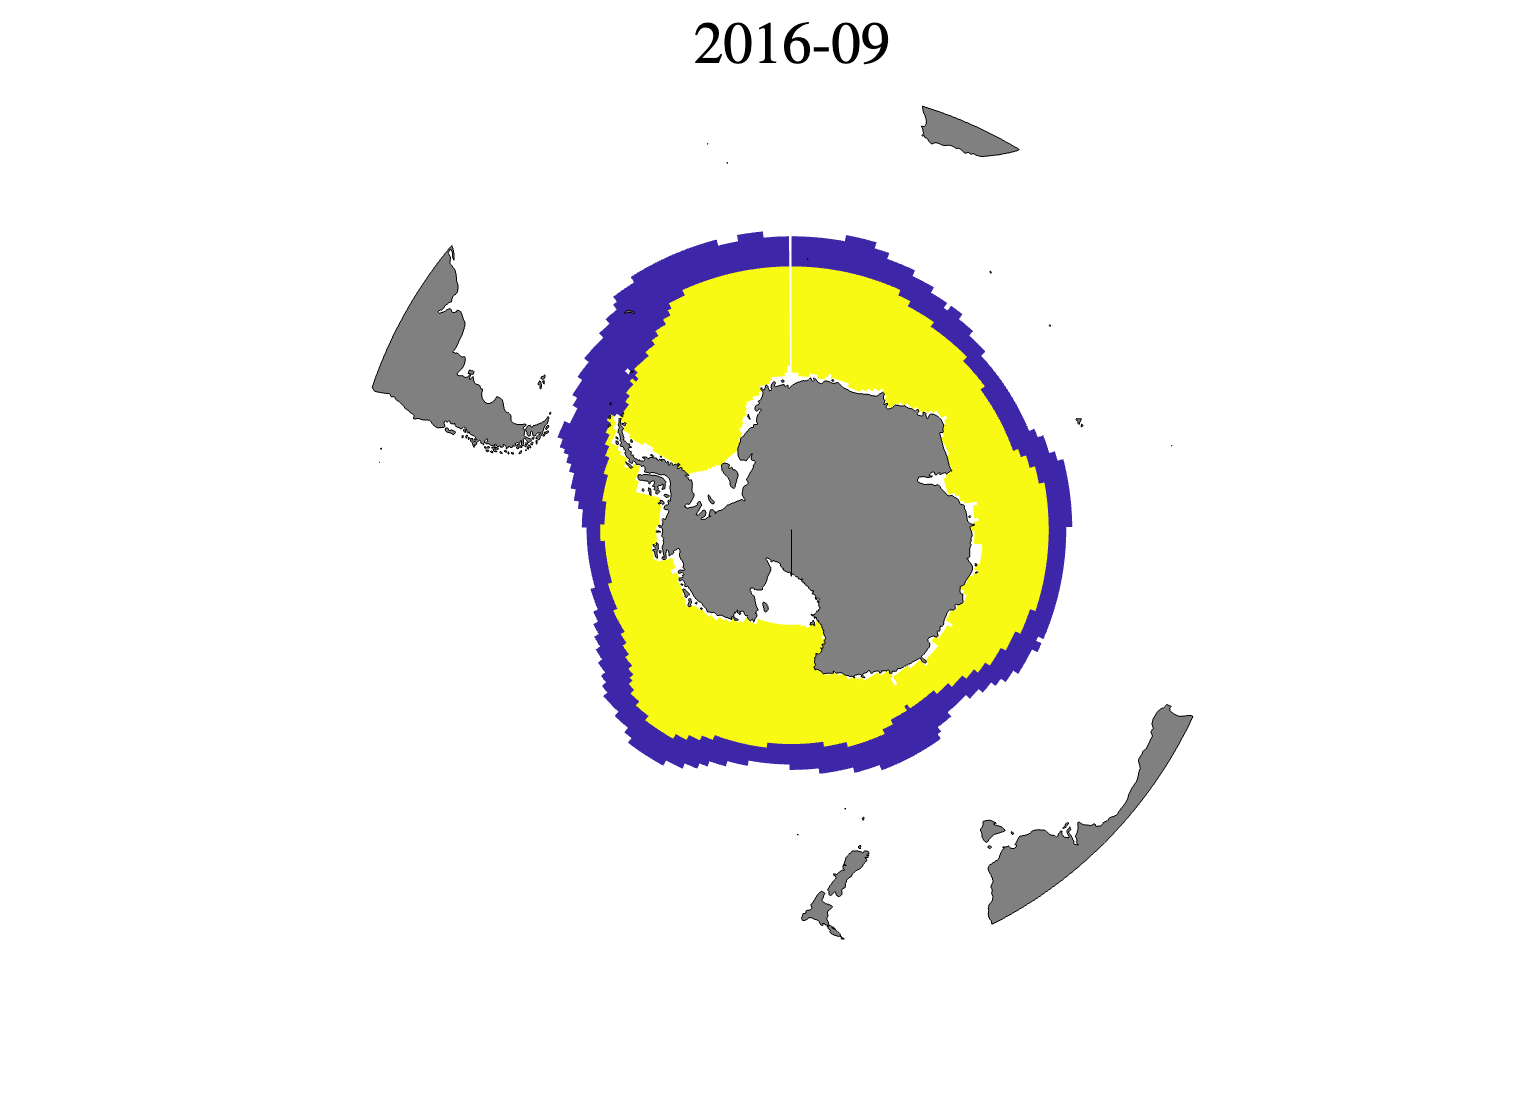

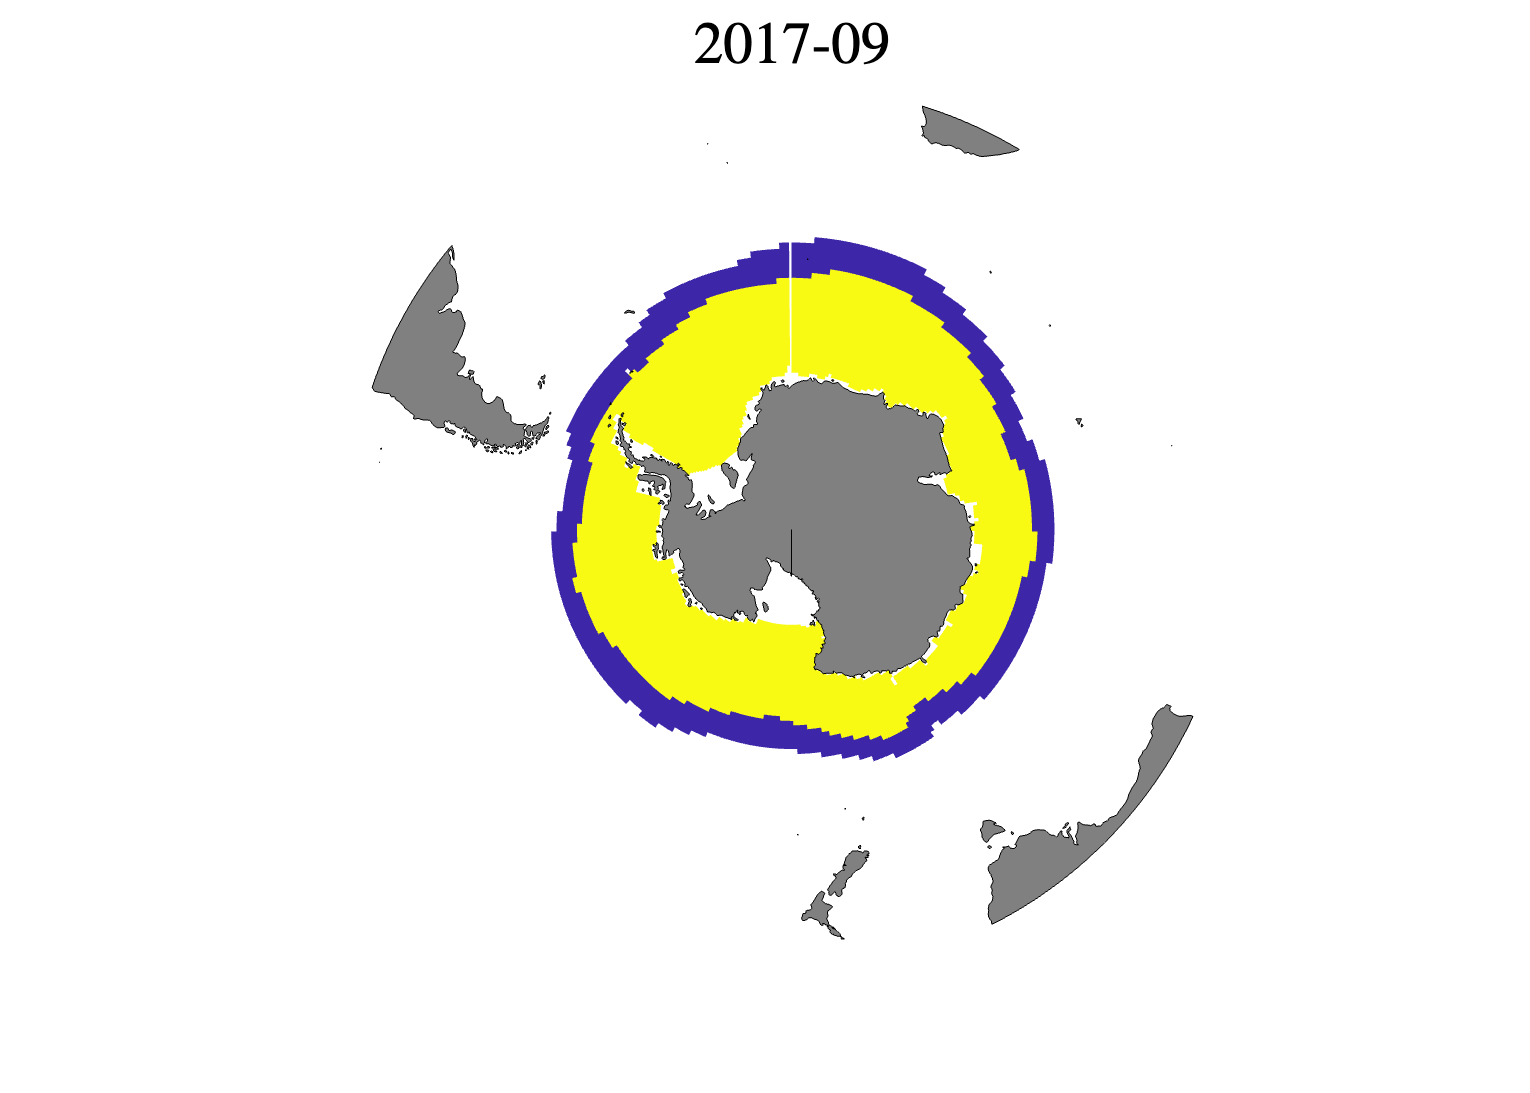

conFigure(30)
%% Clustering gifs
% Columns are data
sector = "SH";
historydir = '/Users/noahday/Maths1/access-forcing-2010-fixed-ic/history/Sep/';
line_width = 2;
FigWidth = 1920;
FigHeight = 1920;
BufferWidth = 200;
Height = 100;
a = dir([historydir '/*.nc']);
n_files = numel(a);
font_size = 20;
clear filenames dirdates MIZ_width_year
for i = 1:n_files
   filenames(i,:) = strcat(historydir,a(i).name);
   dirdates(i,:) = a(i).name(6:end-3);
end

f= figure('PaperPositionMode','manual','visible','off');
f.Position = [1 1 FigWidth FigHeight];
    AX = gca;
    f.Resize = 'off'; f.Units = 'points'; f.PaperUnits = 'points';
    AX.Units = 'points'; AX.Clipping = 'on'; AX.PositionConstraint = 'innerposition';
    AX.InnerPosition = [0 0 FigWidth-BufferWidth FigHeight-Height]*72/96; % converting from pixels to points
    f.OuterPosition = [0 0 FigWidth FigHeight]*72/96; % converting from pixels to points
    f.PaperPosition = [0 0 FigWidth FigHeight]*72/96;% converting from pixels to points
    camlight
    set(gca,'color','w')
    set(gcf,'color','w')

for loop_idx = 1:n_files
    [X_total]= read_data_vec(filenames(loop_idx,:),sector,var_list);
    % Step 0: removing NaNs
    idx1 = isnan(X_total);
    idx = logical(idx1);%;|logical(idx2);
    [len, wid] = size(X_total);
    clear X_new
    count = 1;
    for j = 1:len
        if sum(idx(j,:)) == 0
            X_new(count,:) = X_total(j,:);
        count  = count + 1;
        end
    end
    X_new_unstandard = X_new;
    % Step 1: Standardization
    wid = wid-2;
    for j = 1:wid
        % Calculate mean
        mean_X(j) = mean(X_new(:,j));
        % Calculate standard deviation
        std_X(j) = std(X_new(:,j));
        % Standardise the data
        X_new(:,j) = (X_new(:,j) - mean_X(j))/std_X(j);
    end
    
    % Step 2: Covariance analysis
    X_cov = X_new(:,1:wid);
    C = cov(X_cov);
    
    %% plotting cluster analysis
    %PCA
    figure;
    [coeff,score,latent,tsquared,explained] = pca(X_cov);
    % The rows of coeff contain the coefficients for the five ice variables, and its columns correspond to five principal components.
    % Each column of score corresponds to one principal component. 
    % The vector, latent, stores the variances of the five principal components.
    
    % Reconstruct the centered ingredients data.
    Xcentered = score*coeff';
    X = score(:,1:2);
    num_clusters = 2;
    [idx,C] = kmeans(X,num_clusters);
    
    x1 = linspace(min(X(:,1)),max(X(:,1)),1000);%min(X(:,1)):0.5:max(X(:,1));
    x2 = linspace(min(X(:,2)),max(X(:,2)),1000);%min(X(:,2)):0.5:max(X(:,2));
    [x1G,x2G] = meshgrid(x1,x2);
    XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot
    
    idx2Region = kmeans(XGrid,num_clusters,'MaxIter',200,'Start',C);
 

    % Make worldmap with colour matching
    [len,wid] = size(lat);
    X_map = [idx, X_new(:,end-1:end)];
    k_means = NaN.*ones(len,wid);
    for i = 1:length(idx)
        lat_pos = near1(lat(180,:),X_map(i,2));
        lon_pos = near1(lon(:,180),X_map(i,3));
        k_means(lon_pos,lat_pos) = idx(i); 
    end
    
  
    w = worldmap('world');
        axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
        setm(w, 'Origin', [-90 0 0]);
        setm(w, 'maplatlimit', [-90,-30]);
        setm(w, 'maplonlimit', [-180,180]);
        setm(w, 'meridianlabel', 'off')
        setm(w, 'parallellabel', 'off') 
        setm(w, 'mlabellocation', 60);
        setm(w, 'plabellocation', 10);
        setm(w, 'mlabelparallel', -45);
        setm(w, 'grid', 'off');
        setm(w, 'labelrotation', 'on')
        pcolorm(lat,lon,k_means)
        title(dirdates(loop_idx,:),'Color','black','FontSize',font_size+5) % 'Position',[0.0500 -0.8663 5000],
        land = shaperead('landareas', 'UseGeoCoords', true);
        geoshow(w, land, 'FaceColor', [0.5 0.5 0.5])
        %colorbar
    hold on
    set(gcf,'Color',[1 1 1]); % color of the frame around the figure
    set(gca,'Color','k')%color for the plot area
    set(gca,'XColor',[1 1 1]); % Set RGB value to what you want
    set(gca,'YColor',[1 1 1]); % Set RGB value to what you want
    if loop_idx == 1
        gif('miz_sep.gif','DelayTime',20/n_files,'resolution',100,'overwrite',true)
    else
        gif
    end

    MIZ_width = calculate_miz_width(filenames(loop_idx,:),sector,k_means);
    MIZ_width_year(loop_idx) = mean(MIZ_width(1:end-1));
end

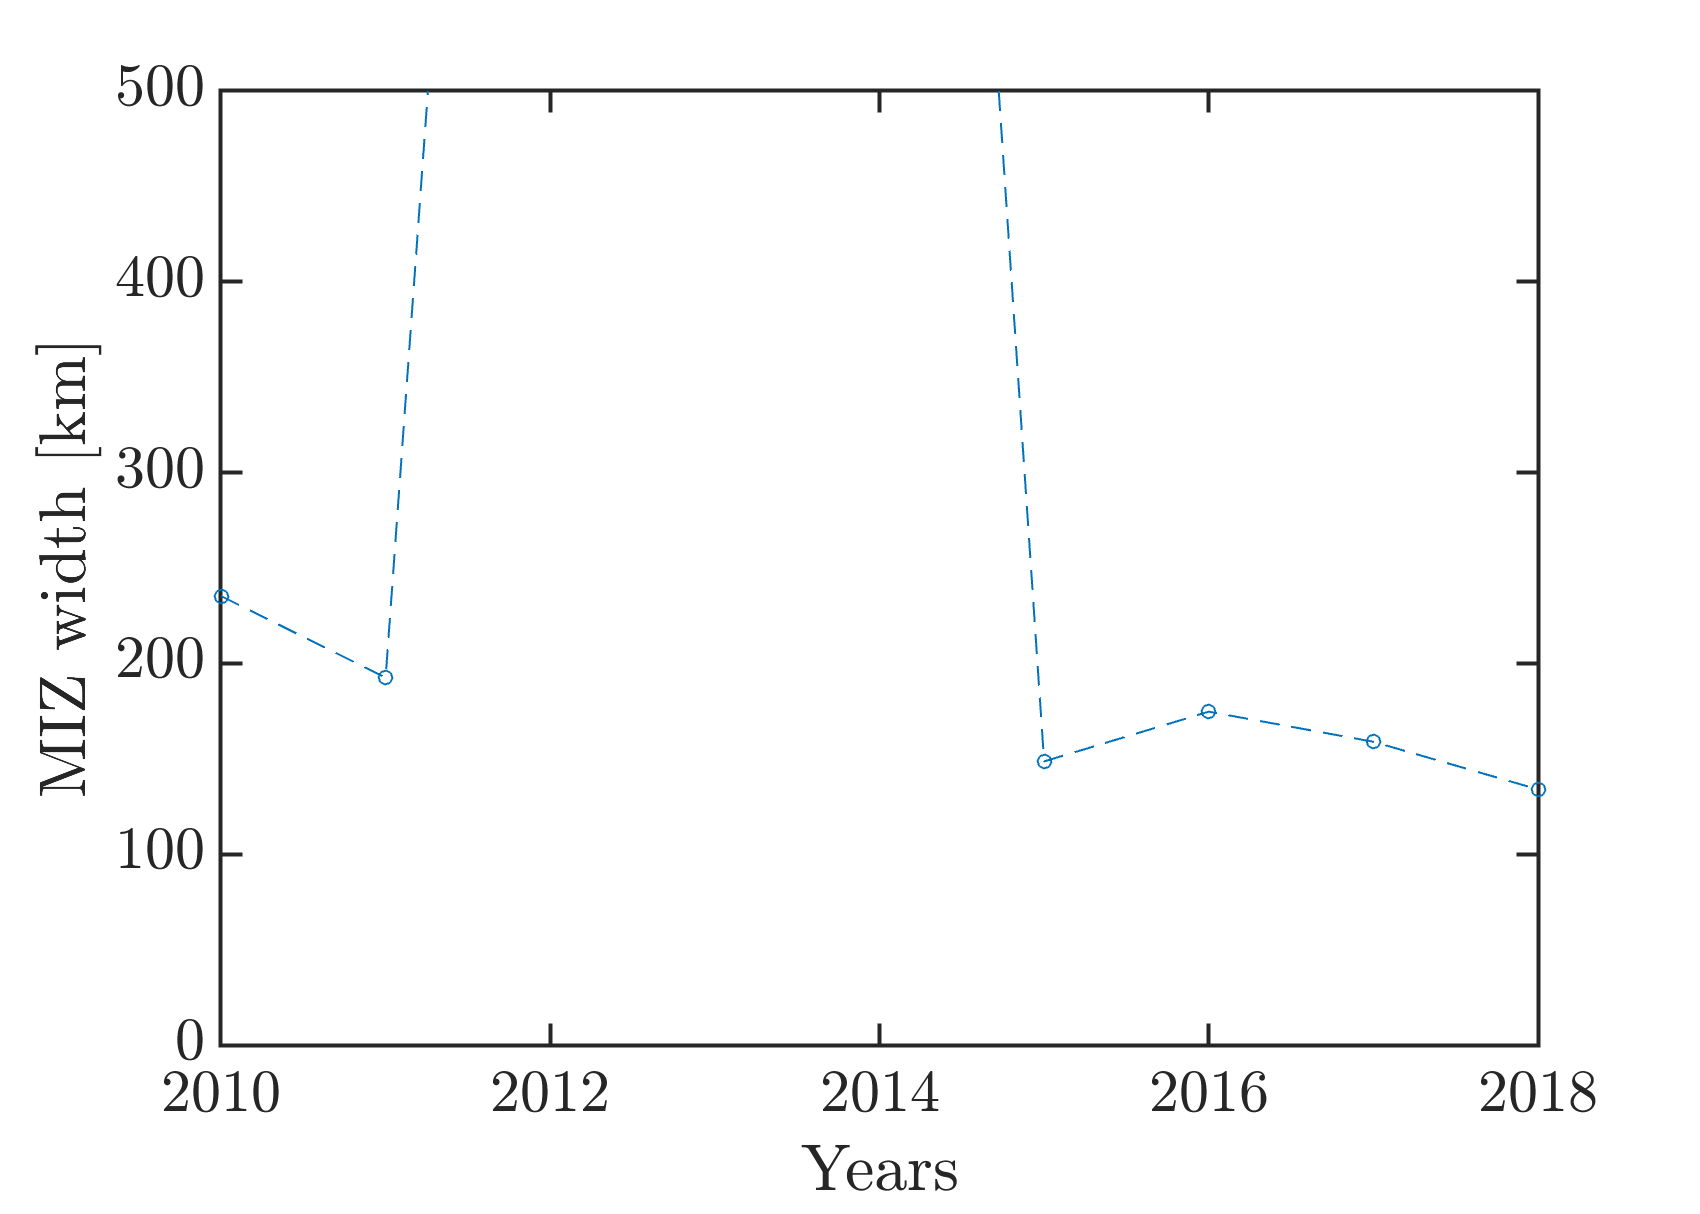


% f = figure;
% plot(1:12,MIZ_width_year,'--o','MarkerSize',7)
% ylabel('MIZ width [km]')
% xticks(1:12)
% xticklabels({'J','F','M','A','M','J','J','A','S','O','N','D'})
% xlabel('Months of 2017')
% ylim([0,800])
% exportgraphics(f,'MIZwidth.pdf','ContentType','vector')

f = figure;
plot(2010:2018,MIZ_width_year,'--o','MarkerSize',7)
ylim([0,500])
ylabel('MIZ width [km]')
%xticks(1:12)
%xticklabels({'J','F','M','A','M','J','J','A','S','O','N','D'})
xlabel('Years')
exportgraphics(f,'MIZwidthyear.pdf','ContentType','vector')

## Functions

function [X_total]= read_data_vec(filename,sector,var_list)
    [aice, sector_mask] = data_format_sector(filename,"aice",sector);
    [lat,lon,~,ulat,ulon] = grid_read('om2');
    lat_vec = reshape(lat(sector_mask),numel(lat(sector_mask)),1);
    lon_vec = reshape(lon(sector_mask),numel(lon(sector_mask)),1);

    NFSD = ncread(filename,"NFSD");
    NCAT = ncread(filename,"NCAT");
    [floe_binwidth, floe_rad_l, floe_rad_h, floe_area_binwidth] = cice_parameters(NFSD);

    X_total = [];
    for i = 1:numel(var_list)
        if var_list{i} == "pancake"
            temp = data_format_sector(filename,"afsdn",sector);
            temp2 =  temp(:,:,1,1)./aice(:,:).*floe_binwidth(1).*100;
            temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
            X_total = [X_total, temp_vec];
        elseif var_list{i} == "large"
            temp = data_format_sector(filename,"afsdn",sector);
            temp2 =  temp(:,:,numel(NFSD),1)./aice(:,:).*floe_binwidth(numel(NFSD)).*100;
            temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
            X_total = [X_total, temp_vec];
        elseif var_list{i} == "strair"
            tempx = data_format_sector(filename,"strairx",sector);
            tempy = data_format_sector(filename,"strairy",sector);
            tempx_vec = reshape(tempx(sector_mask),numel(tempx(sector_mask)),1);
            tempy_vec = reshape(tempy(sector_mask),numel(tempy(sector_mask)),1);
            temp_vec = sqrt(tempx_vec.^2 + tempy_vec.^2);
            X_total = [X_total, temp_vec];
        elseif var_list{i} == "strocn"
            tempx = data_format_sector(filename,"strocnx",sector);
            tempy = data_format_sector(filename,"strocny",sector);
            tempx_vec = reshape(tempx(sector_mask),numel(tempx(sector_mask)),1);
            tempy_vec = reshape(tempy(sector_mask),numel(tempy(sector_mask)),1);
            temp_vec = sqrt(tempx_vec.^2 + tempy_vec.^2);
            X_total = [X_total, temp_vec];
        elseif var_list{i} == "strint"
            tempx = data_format_sector(filename,"strintx",sector);
            tempy = data_format_sector(filename,"strinty",sector);
            tempx_vec = reshape(tempx(sector_mask),numel(tempx(sector_mask)),1);
            tempy_vec = reshape(tempy(sector_mask),numel(tempy(sector_mask)),1);
            temp_vec = sqrt(tempx_vec.^2 + tempy_vec.^2);
            X_total = [X_total, temp_vec];
        elseif var_list{i} == "strcor"
            tempx = data_format_sector(filename,"strcorx",sector);
            tempy = data_format_sector(filename,"strcory",sector);
            tempx_vec = reshape(tempx(sector_mask),numel(tempx(sector_mask)),1);
            tempy_vec = reshape(tempy(sector_mask),numel(tempy(sector_mask)),1);
            temp_vec = sqrt(tempx_vec.^2 + tempy_vec.^2);
            X_total = [X_total, temp_vec];
        elseif var_list{i} == "vel"
            tempx = data_format_sector(filename,"uvel",sector);
            tempy = data_format_sector(filename,"vvel",sector);
            tempx_vec = reshape(tempx(sector_mask),numel(tempx(sector_mask)),1);
            tempy_vec = reshape(tempy(sector_mask),numel(tempy(sector_mask)),1);
            temp_vec = sqrt(tempx_vec.^2 + tempy_vec.^2);
            X_total = [X_total, temp_vec];  
        else
            temp = data_format_sector(filename,var_list{i},sector);
            temp_vec = reshape(temp(sector_mask),numel(temp(sector_mask)),1);
            X_total = [X_total, temp_vec];
        end

    end
    X_total = [X_total, lat_vec, lon_vec];
    
end


function var_out = variable_dict(var_in)
    for i = 1:numel(var_in)
        if var_in{i} == "aice"
            var_out{i} = 'SIC';
        elseif var_in{i} == "hi"
            var_out{i} = 'Ice thickness';
        elseif var_in{i} == "iage"
            var_out{i} = 'Ice age';
        elseif var_in{i} == "fsdrad"
            var_out{i} = 'Floe mean radius';
        elseif var_in{i} == "pancake"
            var_out{i} = 'Pancake ice';
        elseif var_in{i} == "large"
            var_out{i} = 'Sheet ice';
        elseif var_in{i} == "wave_sig_ht"
            var_out{i} = 'Sig. wave height';
        elseif var_in{i} == "ice_present"
            var_out{i} = 'Ice present';
        elseif var_in{i} == "peak_period"
            var_out{i} = 'Peak period';
            
        else
            var_out{i} = var_in{i};
        end
    end
end


function MIZ_width = calculate_miz_width(filename,sector,k_means)
    aice = data_format_sector(filename,'aice',sector);
    [lat,lon,~,ulat,ulon] = grid_read('om2');
    ice_mask =  aice > 0.15;
    k_means(~ice_mask) = NaN;
    idx_miz = isnan(k_means(1,:));
    temp = k_means(1,~idx_miz);
    MIZ = k_means == temp(end);  
    clear MIZ_width
    [len,~] = size(aice);
    for i = 1:len
        ulat_vec_temp = ulat(i,:);
        ulon_vec_temp = ulon(i,:);
        MIZ_vec_temp = MIZ(i,:);
        if sum(MIZ_vec_temp) == 0
            MIZ_width(i,:) = 0;
        else
            south_point = find(MIZ_vec_temp, 1, 'first');
            north_point = find(MIZ_vec_temp, 1, 'last');
            MIZ_width(i,:) = pathdist([ulat_vec_temp(south_point-1),ulat_vec_temp(north_point)],[ulon_vec_temp(south_point),ulon_vec_temp(north_point)],'km');
        end
    end
    MIZ_width = MIZ_width(:,2);
end